# Support Vector Machines Machines: Exercises, II

## Boris Shilov

In this exercise I will attempt to look into the least squares support vector machine formulations using the LS-SVM Matlab toolbox, particularly functon estimation and time series prediction. Unlike normal SVM, LS-SVM is intended to fit a numerical predictive function to the data.

Unlike linear regression, LS-SVM uses only a subset of points to decide the optimal hyperplane. These are the points corresponding to the support vectors, that are outside the $\epsilon$ tube, and changing which would change the optimal hyperplane. By contrast, changing any data point within a training set used for a linear regression classifier would change the classifier.

rng('default')
rng(333)

### sinc regression

We can construct an example dataset using a noisy sinc function. Sinc is thus the true data generating process, and the task of an LS-SVM classifier will be to approximate this function without overfitting to replicate the noise.

X = transpose(-3:0.01:3);
Y = sinc(X) + 0.1 * randn(length(X), 1);
Xtrain = X(1:2: end); Ytrain = Y(1:2: end);
Xtest = X(2:2: end); Ytest = Y(2:2: end);

We can attempt approximation using the RBF kernel, iterating over a small parameter space.

gams = [10, 10e3, 10e6]; sigmas = [0.01, 1, 100];
[sigmasMesh, gamsMesh] = meshgrid(sigmas, gams);
parameterSpace = num2cell([gamsMesh(:), sigmasMesh(:)], 2);

perfList = cellfun(@(cell) crossvalidate({ Xtrain , Ytrain , 'f', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, 10, 'mse'), parameterSpace)

perfList =     0.0125
    0.0140
    0.0172
    0.0381
    0.0113
    0.0111
    0.1376
    0.1162
    0.0895


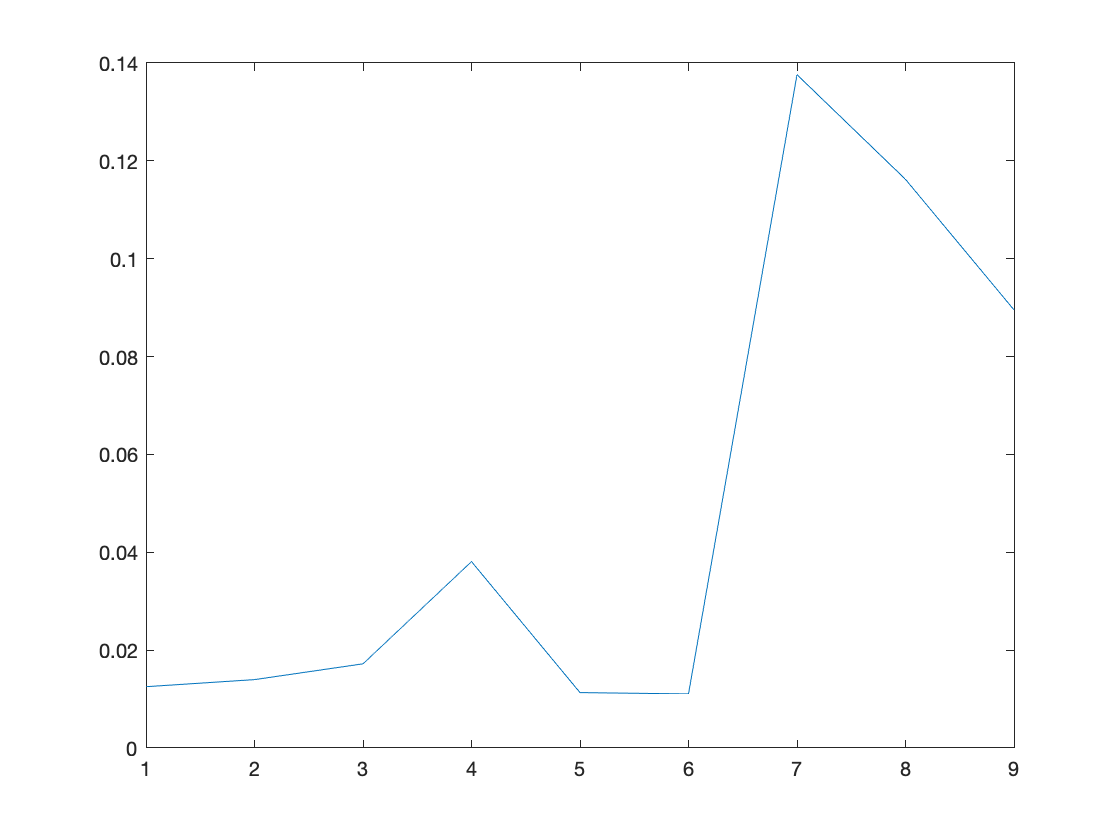

plot(perfList)

It seems that the fifth and sixth models are the best fitting on training set. Their parameters are:

parameterSpace{5} 

ans =        10000           1


parameterSpace{6}

ans =     10000000           1


We can choose between them, as well as the first two models which are relatively well fitting, using the AUC of test set performance.

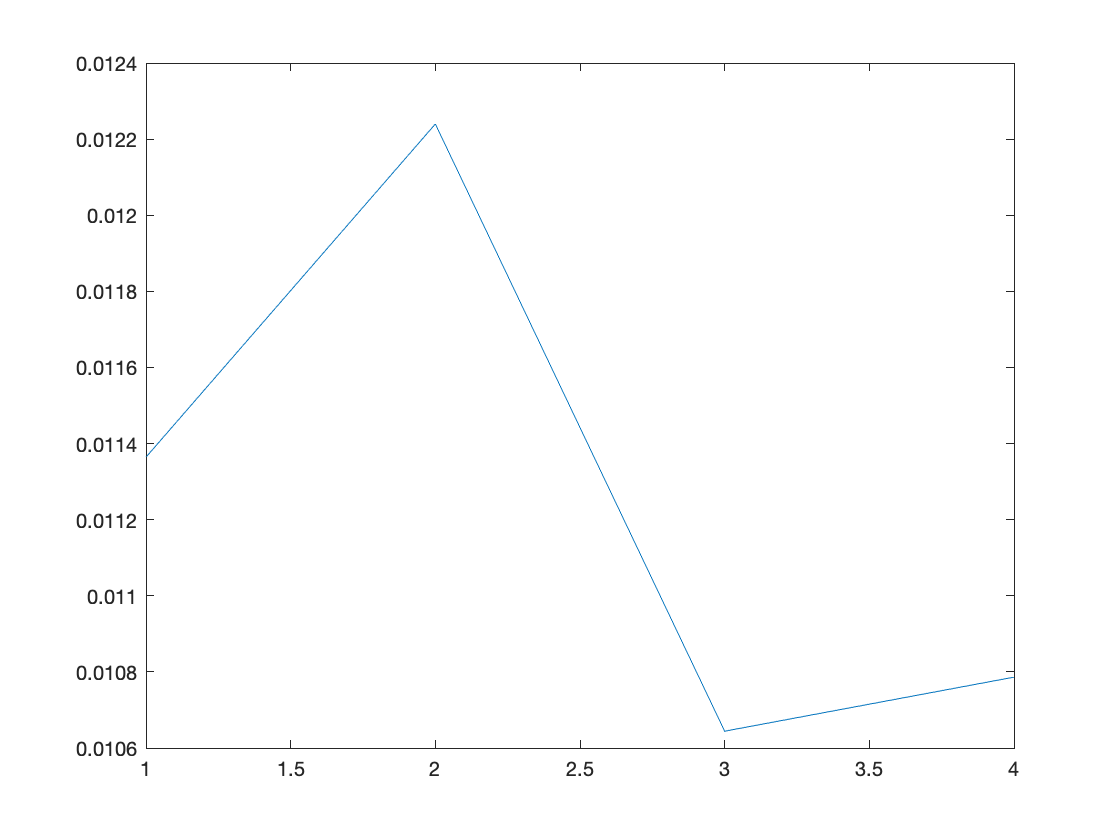

niceParams = cellfun(@(index) parameterSpace{index}, {1 2 5 6}, 'UniformOutput', false);
niceModelSpecs = cellfun(@(cell) { Xtrain , Ytrain , 'f', ...
    cell(:, 1), cell(:, 2), 'RBF_kernel'}, niceParams, 'UniformOutput', false);
niceModels = cellfun(@(cell) trainlssvm(cell), niceModelSpecs, 'UniformOutput', false);
niceSpecAndModel = cellfun(@(index) {niceModelSpecs{index}, ...
    niceModels{index}}, {1 2 3 4}, 'UniformOutput', false);
[Yest, Zt] = cellfun(@(cell) simlssvm(cell{1}, ...
    {cell{2}.alpha, cell{2}.b}, Xtest), niceSpecAndModel, 'UniformOutput', false);
test_mses = cellfun(@(cell) immse(cell, Ytest), Yest);
plot(test_mses)

It seems the fifth model fits the best on the test case. We may visualise the fifth model on the test data points. Here the hollow points are the test set that was not used to fit the data.

modelSpec= {Xtrain, Ytrain, 'f', parameterSpace{5}(1), parameterSpace{5}(2), 'RBF_kernel'};
model = trainlssvm(modelSpec);
Yest = simlssvm(modelSpec, {model.alpha, model.b}, Xtest)

Yest =    -0.0855
   -0.0777
   -0.0695
   -0.0609
   -0.0521
   -0.0430
   -0.0338
   -0.0245
   -0.0151
   -0.0058


figure;
plotlssvm(modelSpec, {model.alpha, model.b});

Start Plotting...

finished


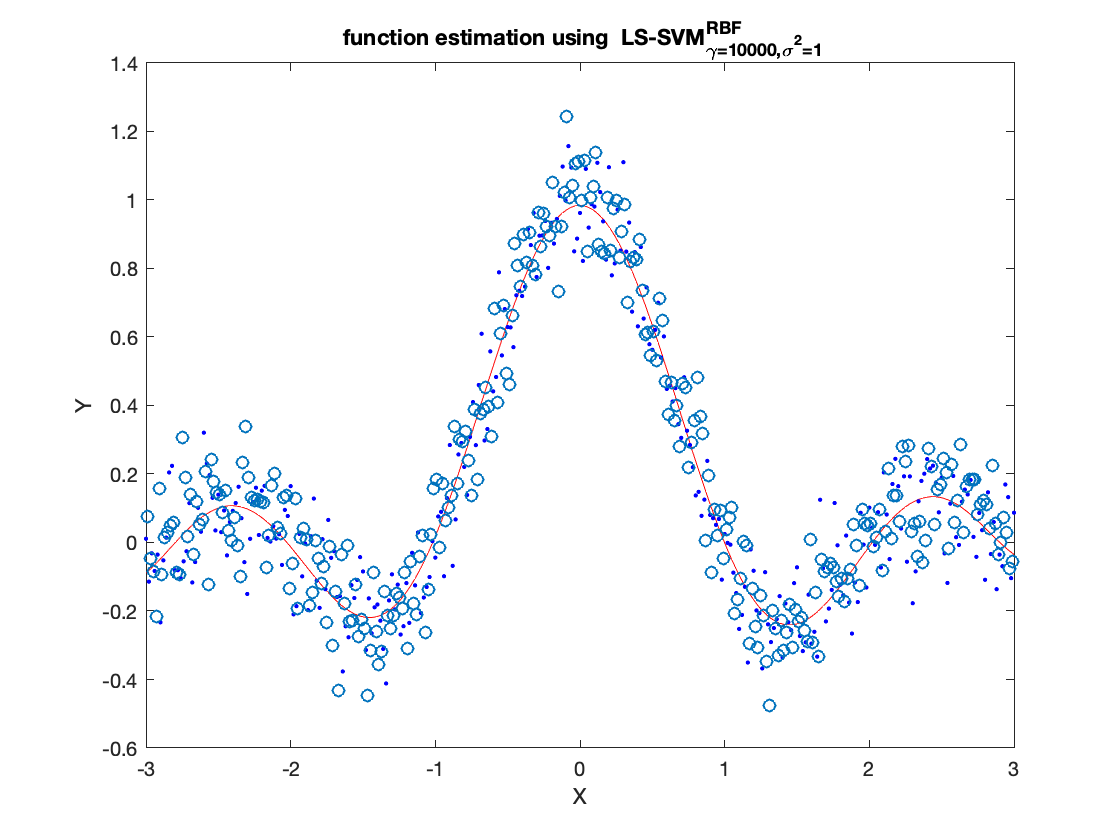

hold on;
scatter(Xtest, Ytest)
hold off;

Since the RBF kernel function estimation SVM is quite flexible, there should exist a pair of parameters that are optimal in the sense that, given these parameters, the resulting SVM is the best approximation of the underlying data-generating function possible. However, as we typically do not have direct access to the data generating process, a broader optimality criterion for parameters is that the resulting SVM is the best performing on some test set among the set of all possible SVMs. Some exceptions to this are possible - for example, there may be multiple near equal maxima or minima in the parameter space. This would correspond to having two or more models that fit the data equally well.

We can compare the resulting model to automatic parameter tuning.

[gamSimp, sigSimp, costSimp] = tunelssvm({Xtrain, Ytrain, 'f', ...
    [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10, 'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         16.254
                                          [sig2]        0.25793
                                          F(X)=         0.011078
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   16.254     0.257929

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.107844e-02     2.7883        -1.3551      initial 
     2           5     1.107844e-02     2.7883        -1.3551      contract outside 
     3           7     1.106566e-02     3.2383        -1.0551      contract inside 
     4           9     1.106566e-02     3.2383     

[gamGrid, sigGrid, costGrid] = tunelssvm({Xtrain, Ytrain, 'f', ...
    [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm', {10, 'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.7174
                                          [sig2]        0.26885
                                          F(X)=         0.011015
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.38423    0.022068
    cost of starting values:           0.01264
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.38422919      1145.3711
                          [sig2]        0.022068      3.2752
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=3.0435     -1.3136 ,F(X)=0.011015;
ITERATION: 2
  dF=1.0242e-05, dX=0.92901, X=2.1218     -1.4302 ,F(X)=0.011005;
Obtained hyper-parameters: [gamma sig2]: 8.3463     0.23925


It appears that we have by chance stumbled upon a slightly better model than determined by these parameters, since the test MSE of our fifth model is better than even the train MSEs found by automated tuning. Both methods produce similar results. Doing more iterations in both algorithms, over a larger space, could probably tune into the value we have found.

### Bayesian tuning

What is the probability that our data were generated by a particular model?

sig = 0.4; gam = 10;
modelSpecBay = {Xtrain, Ytrain, 'f', gam, sig}

modelSpecBay = 1×5 cell array
    {301×1 double}    {301×1 double}    {'f'}    {[10]}    {[0.4000]}


crit_Ls = arrayfun(@(level) bay_lssvm(modelSpecBay, level), [1 2 3])

 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


crit_Ls =   139.7708  789.7909 -724.2877


bayOptims = arrayfun(@(level) bay_optimize(modelSpecBay, level), [1 2 3], 'UniformOutput', false);

A =     2.3247
   -1.2467
    0.6694
   -0.9484
    0.0570
   -5.4108
   -0.8818
    0.6302
    5.4136
    5.7046


 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
 
 

Local minimum found.

Optimization completed because the size of the gradie

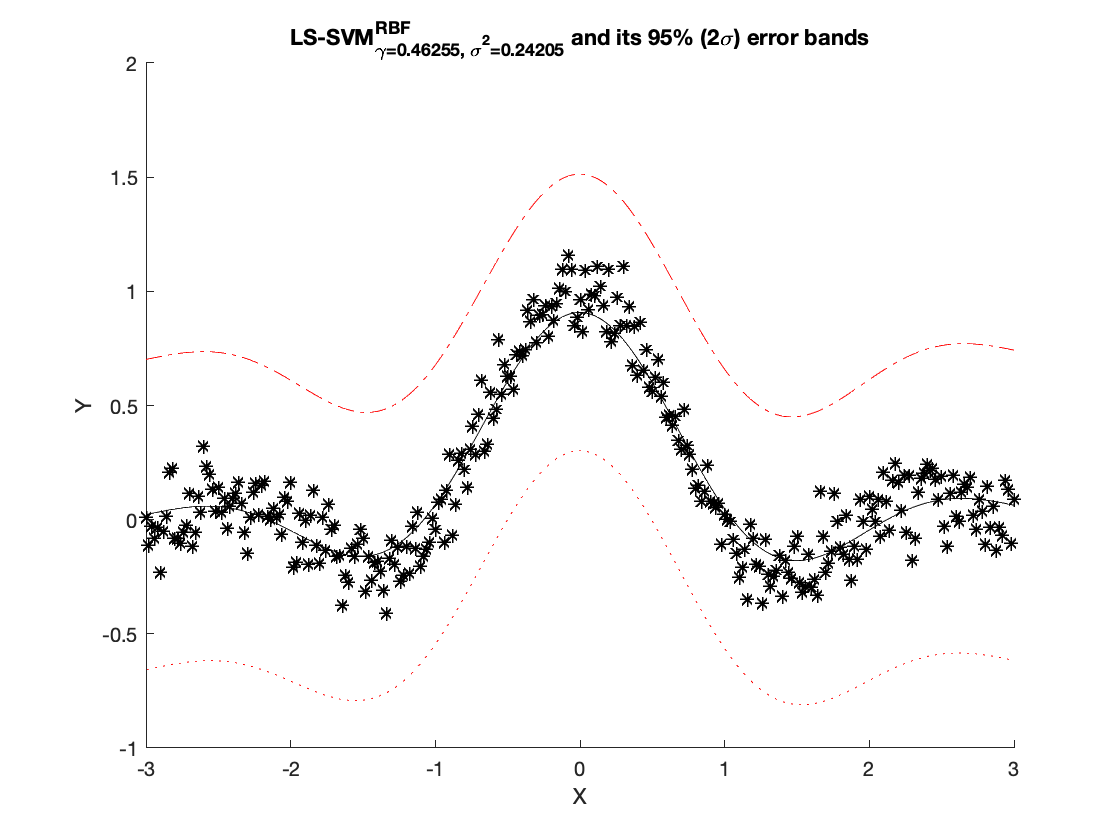

sigErrs =     0.1154
    0.1154
    0.1153
    0.1153
    0.1153
    0.1153
    0.1153
    0.1152
    0.1152
    0.1152


sigErrs = bay_errorbar({Xtrain, Ytrain, 'f', bayOptims{2}.gam, bayOptims{3}.kernel_pars}, 'figure')

This approach using the Bayes rule works as follows: we split the problem of finding the model that is the most likely, given the observed data, into three levels.

### ARD

X = 6.* rand(100 , 3) - 3;
Y = sinc (X(: ,1)) + 0.1.* randn(100 ,1);
[selected, ranking] = bay_lssvmARD ({X, Y,'f', bayOptims{2}.gam, bayOptims{3}.kernel_pars});

ans = 'OPTIMIZING GAMMA AND KERNEL PARAMETERS WITH BAYESIAN FRAMEWORK OVER ALL INPUTS...'

 
 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
 

Local minimum found.

Optimization completed because the size of the gradie

ans = 'testing for 3 inputs'

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<

ans = 'SELECTED INPUT(S) ('discrete'): [1  2]'

ans = 'testing for 2 inputs'

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<

ans = 'SELECTED INPUT(S) ('discrete'): [1]'

### Robust regression

If the data are noisy, robust regression can be used to attempt to disregard the noise and/or outliers to fit closer to the underlying function. We construct a similar sinc dataset to demonstrate this, this time adding more noise.

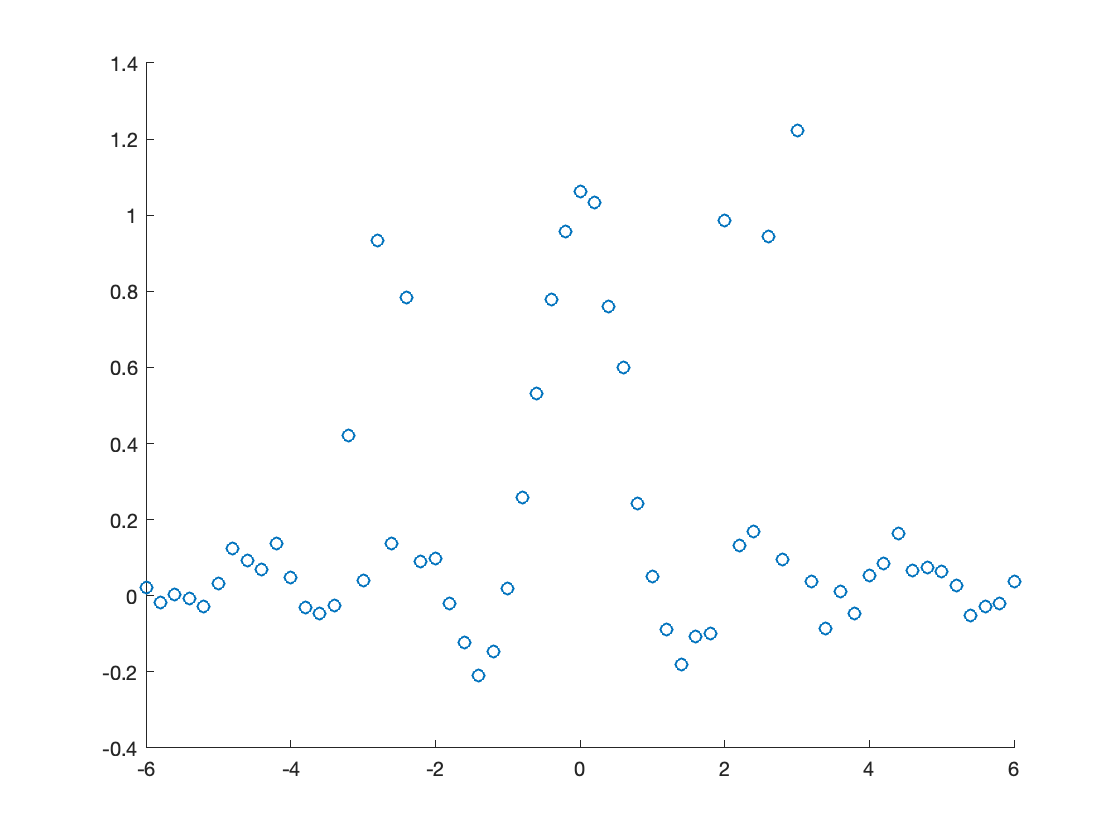

dataGeneratingFun = @(X) sinc(X) + 0.1 * rand(size(X));
X = transpose(-6:0.2:6); Y = dataGeneratingFun(X);
outSet1 = [15 17 19]; outSet2 = [41 44 46];
Y(outSet1) = 0.7 * 0.3 + rand(size(outSet1)); Y(outSet2) = 1.5 * 0.2 + rand(size(outSet2)); 
scatter(X, Y)

What happens if we try naively fitting on these data?

Model = initlssvm(X, Y, 'f', [], [],'RBF_kernel');
tunedNaiveModel = tunelssvm(Model, 'simplex', ...
    'crossvalidatelssvm', {10, 'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         96.14
                                          [sig2]        0.12456
                                          F(X)=         0.069
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   96.14     0.124557

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     6.899979e-02     4.5658        -2.0830      initial 
     2           5     6.899979e-02     4.5658        -2.0830      contract outside 
     3           7     6.899979e-02     4.5658        -2.0830      contract inside 
     4           9     6.899979e-02     4.5658        -2

Start Plotting...

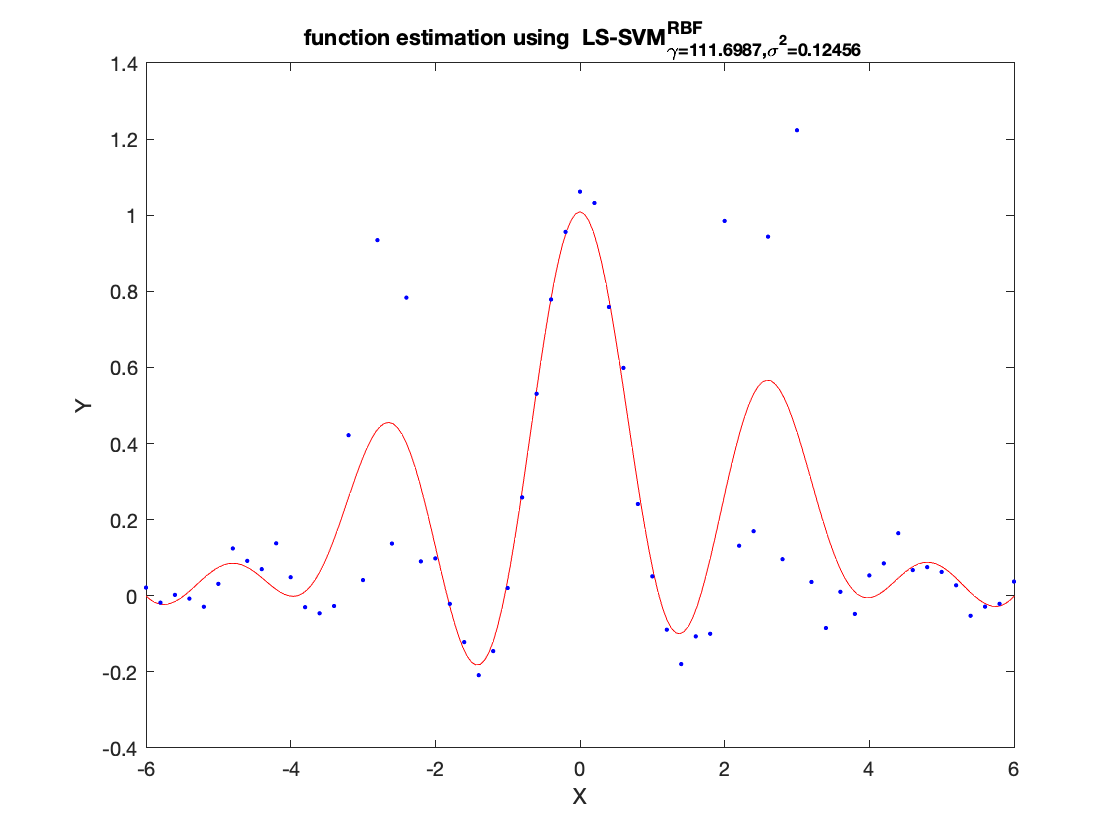

finished


ans = struct with fields:
           type: 'f'
          x_dim: 1
          y_dim: 1
        nb_data: 61
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [61×1 double]
         ytrain: [61×1 double]
       selector: [61×1 logical]
            gam: 111.6987
    kernel_pars: 0.1246
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'c'
    pre_yscheme: 'c'
      pre_xmean: 1.4560e-17
       pre_xstd: 3.5506
      pre_ymean: 0.1988
       pre_ystd: 0.3628
         status: 'trained'
        weights: []
              b: 0.2157
          alpha: [61×1 double]
       duration: 3.7514e-04


plotlssvm(tunedNaiveModel)

Within the outlier regions, the estimation is very far from the true sinc function, being highly influenced by just three points in each region. This also has effects outside the outlier regions. 

By contrast, a robust model should minimize the influence of support vectors with big errors on the final function estimate. A robust Whuber model on this data will generate warning about a lack of inverse but will nonetheless fit fit.

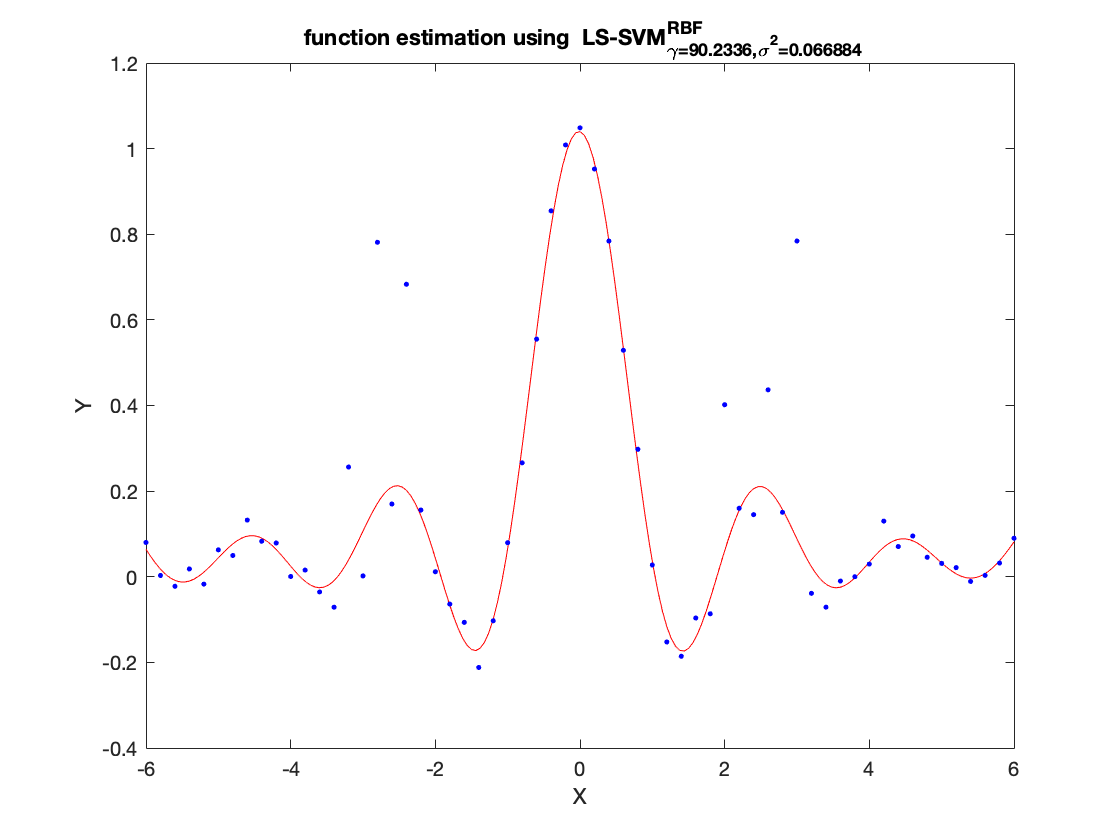

Here the MSE function is used in the naive formulation - since the RMSE will square the residuals before summing them, this amplifies the influence of outliers. By contrast, MAE used in the robust regression penalizes large errors.